xyzI = [50 50 100];
vel_in = 25;
theta = deg2rad(30);
[xB, yB, zB, vB, GB] = bankedTurn(xyzI,vel_in,theta)

xB =   110.3498  110.2943  110.1277  109.8501  109.4620  108.9637  108.3557  107.6385  106.8130  105.8799  104.8402  103.6949  102.4452  101.0924   99.6378   98.0828   96.4291   94.6783   92.8322   90.8926   88.8614   86.7408   84.5329   82.2398   79.8639   77.4076   74.8734   72.2638   69.5814   66.8289   64.0092   61.1250   58.1792   55.1749   52.1150   49.0027   45.8410   42.6331   39.3823   36.0919   32.7651   29.4053   26.0160   22.6004   19.1620   15.7044   12.2310    8.7452    5.2507    1.7508


yB =          0    3.5012    6.9988   10.4894   13.9695   17.4354   20.8838   24.3112   27.7141   31.0891   34.4328   37.7419   41.0129   44.2426   47.4278   50.5652   53.6517   56.6842   59.6596   62.5750   65.4273   68.2137   70.9315   73.5778   76.1501   78.6457   81.0621   83.3968   85.6476   87.8122   89.8883   91.8739   93.7671   95.5657   97.2682   98.8728  100.3777  101.7816  103.0831  104.2807  105.3733  106.3598  107.2392  108.0107  108.6734  109.2266  109.6699  110.0027  110.2248  110.3359


zB =    100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100


vB = 25

GB =          0         0    1.1547


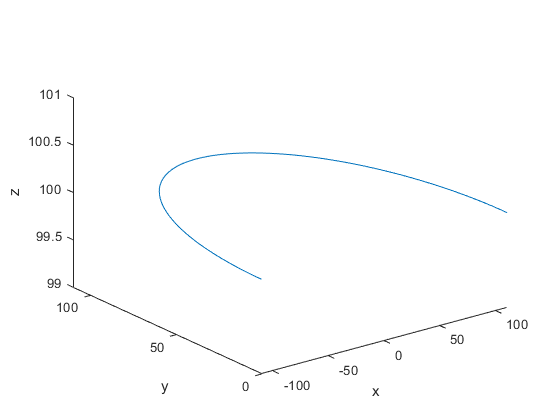

plot3(x,y,z)
xlabel("x")
ylabel("y")
zlabel("z")

function [x, y, z, vel_out, g_forces] = bankedTurn(xyzI, vel_in, theta)
    xI = xyzI(1);
    yI = xyzI(2);
    zI = xyzI(3);
    vel_out = vel_in;
    g = 9.81;
    r = ((vel_in)^2 / g) * cot(theta);
    g_forces = [0 0 1/cos(theta)];
    t = linspace(0,pi,100);
    x = r.*cos(t);
    y = r.*sin(t);
    z = zI + t - t;
end